## Boas práticas

clc;                    % limpa a tela
clear all;              % limpa as variáveis
close all;              % fecha as figuras

## Leitura do RQUIVO .WAV - AUDIOREAD

[y, fs] = audioread('T3_Vogais\Vogal_A.wav');

fs % fs > 2.fmax --> Voltar a função g(n)

fs = 48000

ts     = 1/fs % Tempo em  seg para pegar uma amostra

ts = 2.0833e-05

y % Ampltude do Sinal - Direto/Esquerdo

y =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


nPontos = length(y) % Número de Pontos

nPontos = 360960

vFinal  = (nPontos -1) * ts % Tempo Total em seg

vFinal = 7.5200

tempo   = (linspace(0, vFinal, nPontos)) % Vetor tempo em seg

tempo =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010


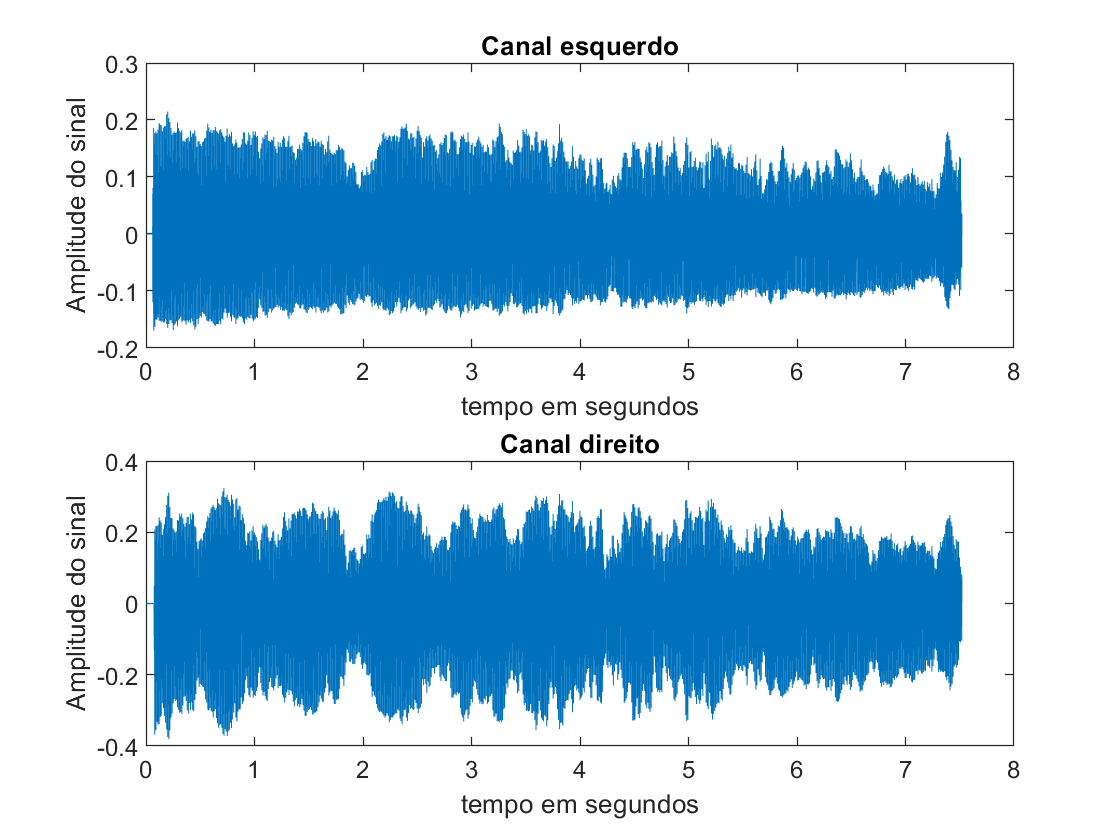


figure(1);
subplot(2,1,1);
plot(tempo, y(:,1));
xlabel('tempo em segundos')
ylabel('Amplitude do sinal')
title('Canal esquerdo')

subplot(2,1,2);
plot(tempo, y(:,2));
xlabel('tempo em segundos')
ylabel('Amplitude do sinal')
title('Canal direito')

## Ouvir um arquivo .wav

% sound(y, fs);
fy = fftshift(fft(y))

fy = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0001 + 0.0001i  -0.0002 + 0.0000i
  -0.0000 + 0.0002i  -0.0002 + 0.0002i
   0.0001 + 0.0001i   0.0000 - 0.0001i
   0.0000 + 0.0002i  -0.0002 + 0.0000i
   0.0004 + 0.0001i   0.0002 - 0.0001i
   0.0001 - 0.0001i   0.0002 + 0.0000i
   0.0001 - 0.0001i   0.0000 - 0.0002i
  -0.0000 - 0.0000i  -0.0000 + 0.0000i
   0.0002 - 0.0001i  -0.0000 + 0.0000i


## Visualizar a FFT e interpretar

frequencia = linspace(-fs/2, fs/2, nPontos) % Eixo x

frequencia = 	1.0e+04 *

   -2.4000   -2.4000   -2.4000   -2.4000   -2.3999   -2.3999   -2.3999   -2.3999   -2.3999   -2.3999   -2.3999   -2.3999   -2.3998   -2.3998   -2.3998   -2.3998   -2.3998   -2.3998   -2.3998   -2.3997   -2.3997   -2.3997   -2.3997   -2.3997   -2.3997   -2.3997   -2.3997   -2.3996   -2.3996   -2.3996   -2.3996   -2.3996   -2.3996   -2.3996   -2.3995   -2.3995   -2.3995   -2.3995   -2.3995   -2.3995   -2.3995   -2.3995   -2.3994   -2.3994   -2.3994   -2.3994   -2.3994   -2.3994   -2.3994   -2.3993


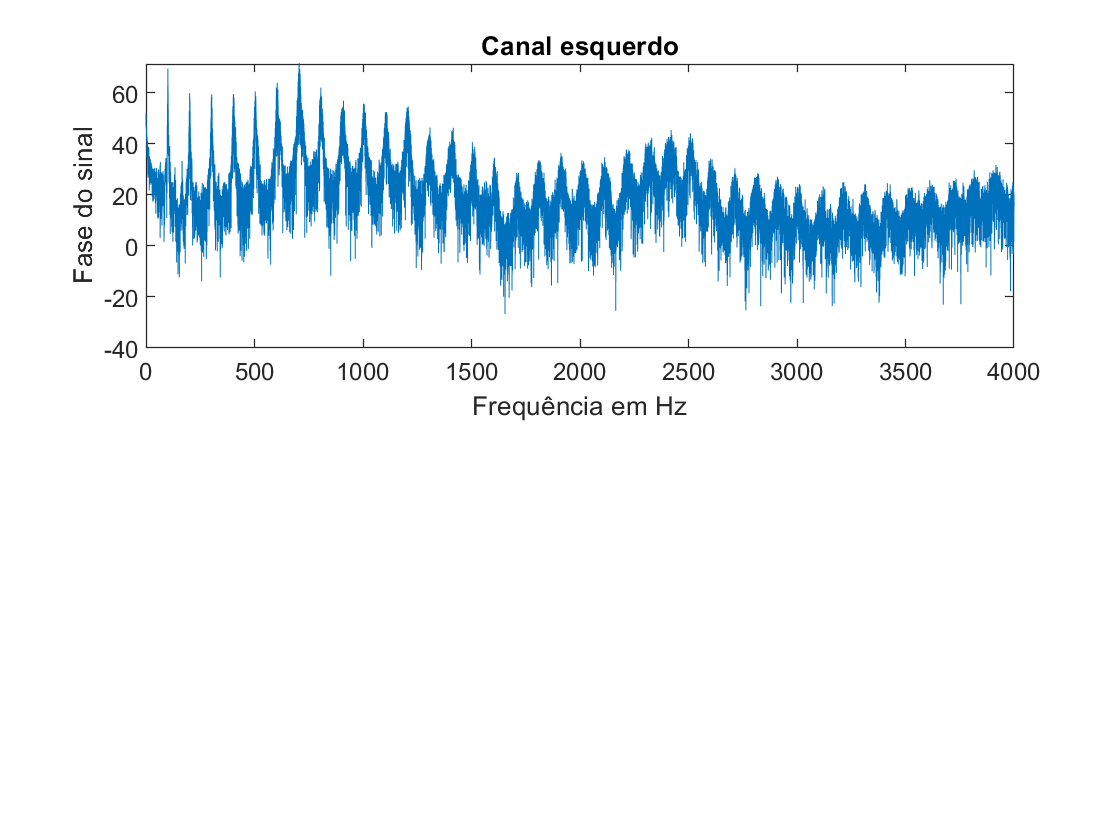



figure(2);
subplot(2,1,1);
plot(frequencia, db(abs(fy(:,1))));
xlim([0 4000]);   % ZOOM
xlabel('Frequência em Hz')
ylabel('Fase do sinal')
title('Canal esquerdo')


% xlim([-2000 2000]);   % ZOOM
% ylim([0 4200]);






